% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp

# Optimiziation-based Robot Control

## Introduction

In the last lesson, you the concept of task-space singularities and a particular way to address them. 

In this lesson, we will revisit the topic of robot control using quadratic optimiziation formalism.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

## Notation

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- ${\it \bf h} \in\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{{\it \bf h}}\in\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- ${\it \bf{p}},{\it \bf{t}},\cdots\in \mathbb{H}_p$: pure quaternions. They represent points, positions, and translations. They are quaternions for which $\text{Re}\left({\it \bf h}\right)=0$.

- ${\it \bf r}\in\mathbb{S}^3$: unit quaternions. They represent orientations and rotations. They are quaternions for which $||{\it \bf h}||=1$. 

- $\underline{\it \bf x} \in$$\underline{\mathcal{S}}$: unit dual quaternions. They represent poses and pose transformations. They are dual quaternions for which $||{\it \bf h}||=1$.

- $\underline{{\it \bf l}}\in \mathcal{H}_p\cap$$\underline{\bf{\mathcal{S}}}$: a Plücker line. 

- $\underline{{\it \bf \pi}}\in \left\{ P\left(\underline{{\it \bf \pi}}\right) \in \mathbb{H}_p\right\}\cap\underline{\bf{\mathcal{S}}}$: a plane.

- $\theta,a,b,\cdots\in\mathbb{R}$: real numbers. 

- ${\it \bf q,\cdots}\in\mathbb{R}^n:$real vectors.

- ${\it \bf J}, {\it \bf A}, {\it \bf B}, \cdots \in \mathbb{R}^{m\times n}:$ real matrices.

## Robot definition

The concepts of this lesson apply to any manipulator robot. However, to have a more concrete understanding using DQ Robotics, consider the same robot as used in the past lesson.

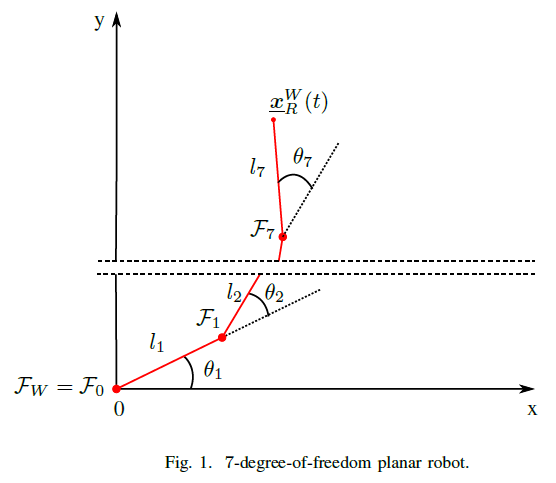

- Let the robot $R$ be a 7-DoF planar robot, as drawn in Fig.1. 

- Let $\mathcal{F}_W$ be the world-reference frame. 

- Let $\underline{\it \bf{x}}_R^W(t)\triangleq\underline{\it \bf{x}}_R$ $\in$$\underline{\mathcal{S}}$ represent the pose of the *end effector*. 

- Let $R$ be composed of seven rotational joints that rotate about their z-axis, composed in the joint-space vector ${\it \bf q}\left(t\right)\triangleq{\it \bf q}=\left[\theta_{1}\ \theta_{2}\ \theta_{3}\ \theta_{4}\ \theta_{5}\ \theta_{6}\ \theta_{7}\right]^{T}$ with $\theta_{i}\left(t\right)\triangleq\theta_{i}\in\mathbb{R}$ for $i=1,2,\ldots,7$. The rotation of the reference frames of each joint coincide with the rotation of $\mathcal{F}_W$ when $\theta_{i}=0$. The length of the joints are $l_i \in$$\mathbb{R}^+-\{0\}$.

- Consider that we can freely control the joint vector ${\it \bf q}$.

This robot can be modeled by the following class.

Let us instantiate our robot as follows

seven_dof_planar_robot = SevenDofPlanarRobotDH.kinematics();

## A brief review of quadratic optimization

At some point in your education you might have been introduced to optimization problems. There are many types of optimization problems and in this lesson we will address only two types, which are enough to solve a large class of robot control problems.

The first type is called unconstrained quadratic optimization of type


$$\min_{\dot{\it \bf q}}\  \mathcal{F}\left(q\right)$$


where $\mathcal{F}\left(q\right)\in\mathbb{R}^+$ is a quadratic *objective function* that depends on the current joint configuration. Note that it is called an *optimization problem*, and **NOT** an equation (note that there is no equality sign). In mathematical optimiziation terminology, $\dot{\it \bf q}$ is called the decision variable. You can read that as "find the $\dot{\it \bf q}$ that minimizes $ \mathcal{F}\left(q\right)$". The solution for an unconstrained quadratic optimization problem can be found analitically. In this lesson we will call that minimizer as $\dot{\it \bf q}^o$.  

The second type of optimization problem that we will address is called Quadratic Programming (QP), which is a linearly-constrained quadratic optimization problem, in the form


$$\min_{\dot{\it \bf q}}\ \ \ \ \ \ \mathcal{F}\left(q\right) \\
\text{subject to}\ {\it \bf W}\dot{\it \bf q}\preceq{\it \bf w}$$


where $ {\it \bf W}\in\mathbb{R}^{n\times p}$ and $ {\it \bf w}\in\mathbb{R}^{p}$ represent $p$ linear constraints. Note that we use $\preceq$ and not $\leq$ because we are representing element-wise column inequalities. You can read that QP as "find $\dot{\it \bf q}$ that minimizes $ \mathcal{F}\left(q\right)$, subject to ${\it \bf W}\dot{\it \bf q}$ less or equal to ${\it \bf w}$". The general solution for a QP has to be obtained using a numerical method. Similarly to the unconstrained case, in this lesson we will call that minimizer as $\dot{\it \bf q}^o$.  

## The damped pseudo-inverse as the solution of an unconstrained quadratic optimiziation problem

In the last lesson the meaning of the damping factor was introduced in the point-of-view of the SVD of the robot's task Jacobian.

The damping factor can be trivially understood when we re-write the robot control problem in the following way


$$\min_{\dot{\it \bf q}}\  ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2+\lambda^2|| \dot{\it \bf q}||^2$$


where ${\it \bf J}\in\mathbb{R}^{n\times m}$ is the task Jacobian for a $n-$DoF robot and a $m-$DoF task. In addition, $\eta\in\mathbb{R}^+-\{0\}$ is the proportional gain of the controller and $\tilde{\it \bf x}\in\mathbb{R}^m$ is the task error. Lastly, $\lambda \in \mathbb{R}$ is the damping factor. 

Note that we are balancing two terms in the objective function. The first term, $ ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2$, will be high when the task error is high and zero when the task error is zero. The second term, $\lambda^2||\dot{\it \bf q}||^2$, will penalize high joint velocities depending on the size of the damping factor. As we saw in practice in the last lesson, the damping factor is used as a term to balance task error convergence and the norm of the joint velocities.

Given that we have an unconstrained quadratic optimization problem which is, by definition, convex, the solution is straightforward. The optimum is where the first-order partial derivative of the objective function with respect to the decision variable equals to zero. Hence


$$\frac{\partial}{\partial\dot{\it \bf q}}\left( ||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2\right) = 0$$



$$\frac{\partial}{\partial\dot{\it \bf q}}\left[ ({\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x})^T({\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x})\right] = 0$$



$$\frac{\partial}{\partial\dot{\it \bf q}}\left(  \dot{\it \bf q}^T{\it \bf J}^T{\it \bf J}\dot{\it \bf q} +  2 \dot{\it \bf q}^T{\it \bf J}^T\tilde{\it \bf x} + \eta^2\tilde{\it \bf x}^T\tilde{\it \bf x}+\lambda^2\dot{\it \bf q}^T\dot{\it \bf q}\right) = 0$$



$$2{\it \bf J}^T{\it \bf J}\dot{\it \bf q} +  2{\it \bf J}^T\tilde{\it \bf x} +2\lambda^2\dot{\it \bf q} = 0$$



$$\left({\it \bf J}^T{\it \bf J} +\lambda^2{\it \bf I}\right)\dot{\it \bf q} = -  {\it \bf J}^T\tilde{\it \bf x}$$



$$\dot{\it \bf q} = -  \left({\it \bf J}^T{\it \bf J} +\lambda^2{\it \bf I}\right)^{-1}{\it \bf J}^T\tilde{\it \bf x}$$


## QP-based robot control: hard joint limits

Using unconstrained optimization to solve robot-control tasks is useful in some cases, but most tasks have what we call *hard limits*. They are called that way in the sense that if those limits are joint-space or task-space limits that cannot be trespassed. For instance, joint limits are a physical type of hard limit. The controller cannot command the robot to move over its joint limits.

When performing kinematic control, the decision variable are the joint velocities and not the joint positions. Therefore, we need to write the joint limits as a linear inequality that depends on the joint velocities. 

Suppose that the lower joint limits are ${\it \bf q}^-\in\mathbb{R}^n$ and the upper joint limits are ${\it \bf q}^+\in\mathbb{R}^n$. The most common way implementing joint limits using a QP is as follows


$$\min_{\dot{\it \bf q}}\ \ \ \ \ \ \||{\it \bf J}\dot{\it \bf q}+\eta\tilde{\it \bf x}||^2+\lambda^2|| \dot{\it \bf q}||^2 \\
\text{subject to}\ {\it \bf W}_{JL}\dot{\it \bf q}\preceq{\it \bf w}_{JL}$$


where


$${\it \bf W}_{JL}=\left[\matrix{
-{\it \bf I} \cr
{\it \bf I} \cr
}\right]$$


and 


$${\it \bf w}_{JL}=\left[\matrix{
-\eta_{JL}\min\left\{{\it \bf q}^{-},\left({\it \bf q}^{-}-{\it \bf q}\right)\right\} \cr
\eta_{JL}\max\left\{{\it \bf q}^{+},\left({\it \bf q}^{+}-{\it \bf q}\right)\right\} \cr
}\right].$$


where $\eta_{JL}\in\mathbb{R}^+-\{0\}$ is a configurable gain. In general, we choose $\eta_{JL}=1$.

The main idea behind this constraint is to constrain the velocity of the joint in the direction of the joint limit. 

DQ Robotics Example